# Electricity Revenue and Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

price = readmatrix("./data/electricity.xlsx", Sheet="price");
usage = readmatrix("./data/electricity.xlsx", Sheet="usage");
yr = readmatrix("./data/electricity.xlsx", Sheet="yr");
mth = readmatrix("./data/electricity.xlsx", Sheet="mth");

revenue = price.*usage;
size(revenue)

ans =     12    26


## Task 1

You can use the [`surf`](https://www.mathworks.com/help/matlab/ref/surf.html) function to visualize an *m*-by-*n* matrix by representing each value in the matrix as the height of a surface.

`surf``(``A``)`

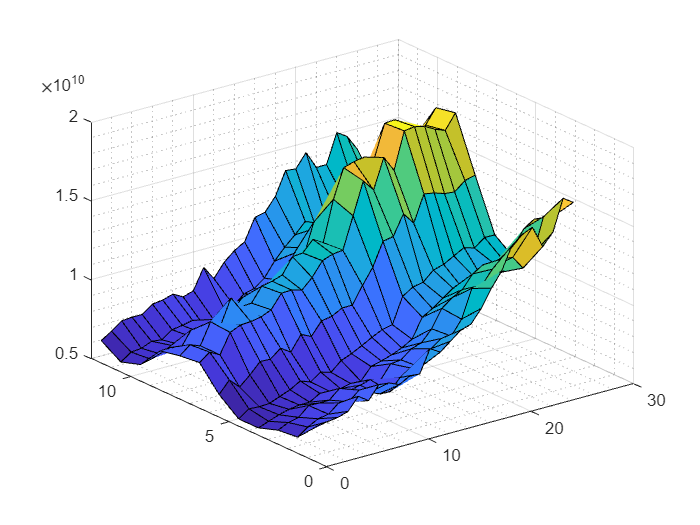

surf(revenue)
grid minor

## Task 2

Just like the `plot` function, the data are plotted against the index values if you don't specify independent variables. If you want to specify the *x* and *y* values, you can pass those as vector input to the `surf` function and other matrix visualization functions.

`surf``(``X``,``Y``,``matrix``)`

If `matrix` is an m-by-n matrix, *x* is an *n*-element vector that describes the columns, and *y* is an *m*-element vector that describes the rows.

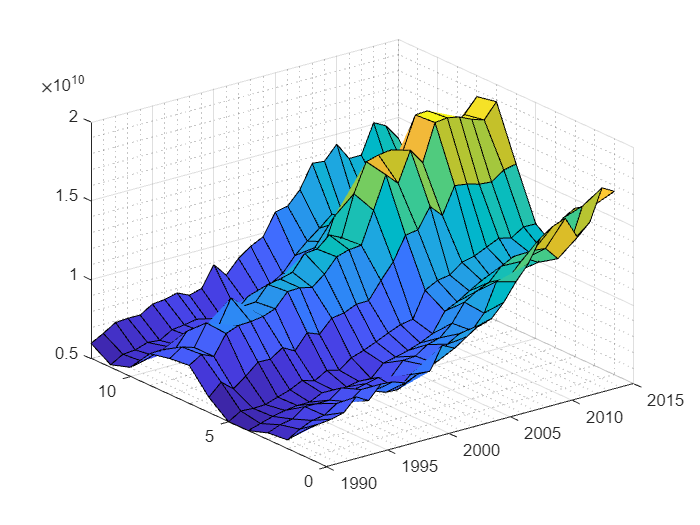

surf(yr, mth, revenue)
grid minor

## Task 3

You can use the same syntax with the `mesh` function.

`mesh``(``X``,``Y``,``matrix``)`

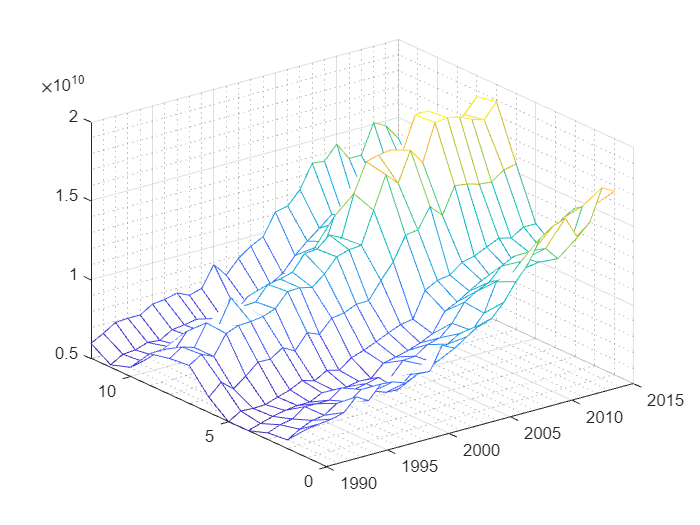

mesh(yr, mth, revenue)
grid minor

## Task 4

You can use a contour plot to visualize matrix data in two dimensions.

`contour``(``X``,``Y``,``matrix``)`

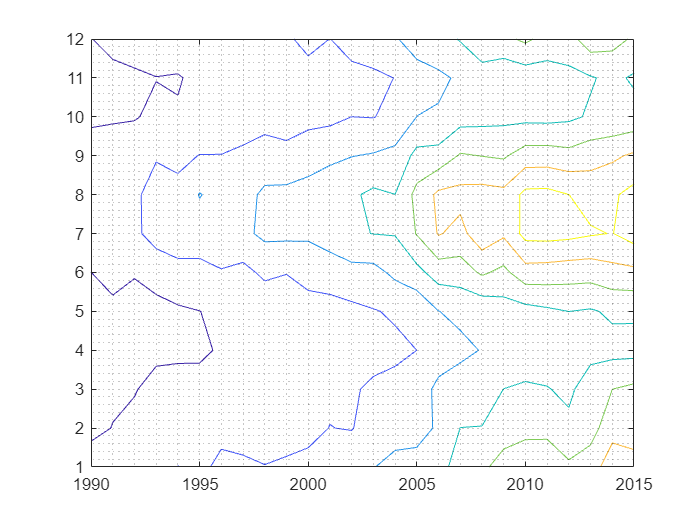

contour(yr, mth, revenue)
grid minor